# Sn×m  seasonal filters to deseasonalize a time series (using a multiplicative decomposition).

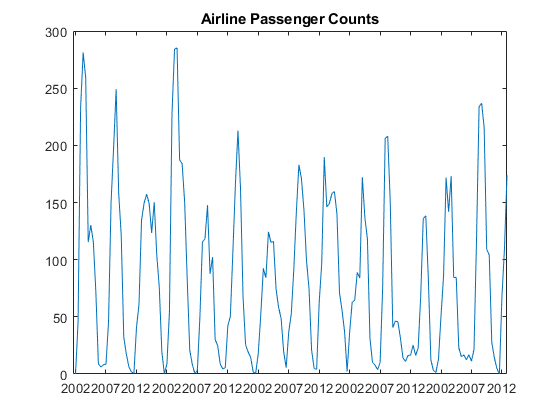

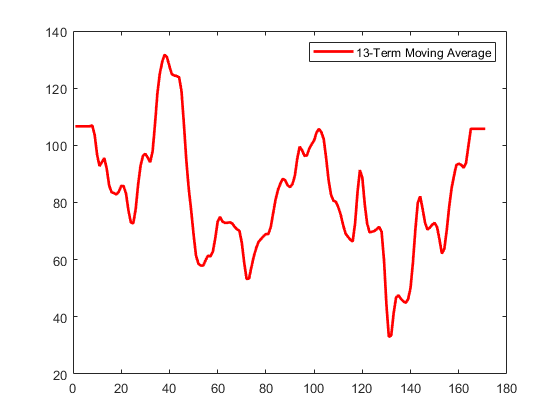

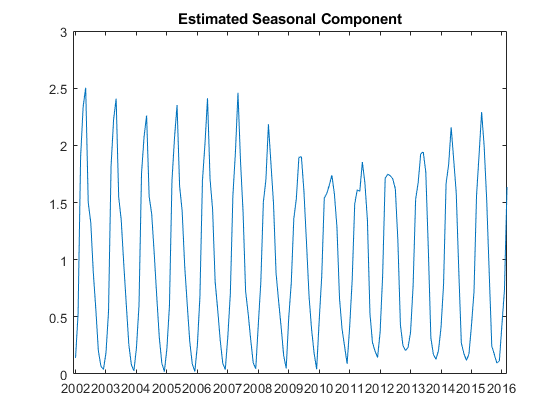

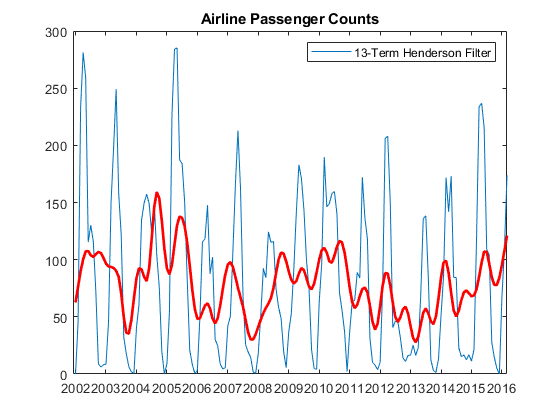

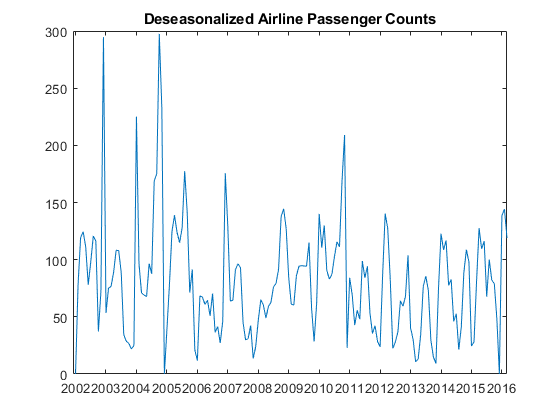

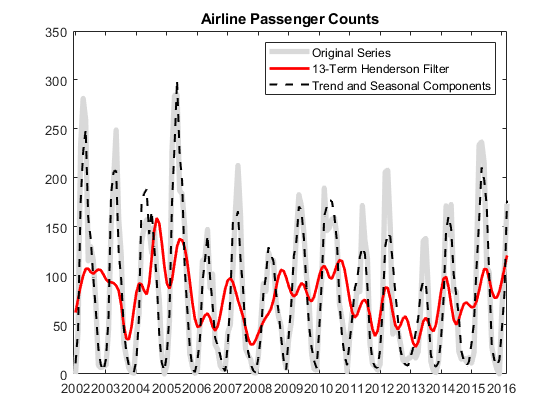

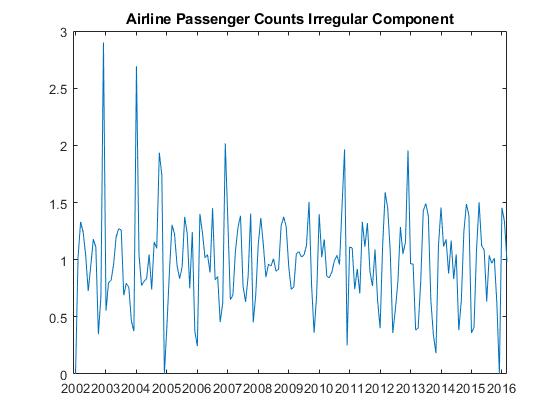


load('C:\PROJECT_FILES\INPUT_DATA\PPT\ppt_anomaly\PPT_ANOMALY.mat')


%y = PPT_ANOMALY(1,:);
y = MEAN_PPT(1,:);
T = size(y,2);

figure
plot(y)
h1 = gca;
h1.XLim = [0,T];
h1.XTick = 1:12:T;
h1.XTickLabel = datestr(TIME(1:60:T),10);
title 'Airline Passenger Counts';
hold on



**Estimate and remove the linear trend. Apply a 13-term symmetric moving average, repeating the first and last observations six times to prevent data loss. Use weight 1/24 for the first and last terms in the moving average, and weight 1/12 for all interior terms.**

sW13 = [1/24;repmat(1/12,11,1);1/24];
yS = conv(y,sW13,'same');
yS(1:6) = yS(7); yS(T-5:T) = yS(T-6);

xt = y./yS;

h = plot(yS,'r','LineWidth',2);
legend(h,'13-Term Moving Average')
hold off


# Create seasonal indices.

**The data is monthly, with periodicity 12, so the first element of sidx is a vector with elements 1, 13, 25,...,133 (corresponding to *****October****** observations). **

s = 12;
sidx = cell(s,1); % Preallocation

for i = 1:3       %Starting from October
 sidx{i,1} = (i+9):s:T;
end

for j=1:9       % To January
  sidx{(j+3),1} = j:s:T;
end


# **Apply an S(3,3) filter for Seasonal signal correction.**

Apply a 5-term *S(*3×3) seasonal moving average to the detrended series `xt`. That is, apply a moving average to the January values (at indices 1, 13, 25,...,133), and then apply a moving average to the February series (at indices 2, 14, 26,...,134), and so on for the remaining months.

Use asymmetric weights at the ends of the moving average (using `conv2`). Put the smoothed values back into a single vector.

To center the seasonal component around one, estimate, and then divide by, a 13-term moving average of the estimated seasonal component.

% S3x3 seasonal filter
% Symmetric weights
sW3 = [1/9;2/9;1/3;2/9;1/9];
% Asymmetric weights for end of series
aW3 = [.259 .407;.37 .407;.259 .185;.111 0];

% Apply filter to each month
shat = NaN*y;
for i = 1:s
    ns = length(sidx{i});
    first = 1:4;
    last = ns - 3:ns;
    dat = xt(sidx{i});
    
    sd = conv(dat,sW3,'same');
    sd(1:2) = conv2(dat(first),1,rot90(aW3,2),'valid');
    sd(ns  -1:ns) = conv2(dat(last),1,aW3,'valid');
    shat(sidx{i}) = sd;
end

% 13-term moving average of filtered series
sW13 = [1/24;repmat(1/12,11,1);1/24];
sb = conv(shat,sW13,'same');
sb(1:6) = sb(s+1:s+6); 
sb(T-5:T) = sb(T-s-5:T-s);

% Center to get final estimate
s33 = shat./sb;

figure
plot(s33)
h2 = gca;
h2.XLim = [0,T];
h2.XTick = 1:12:T;
h2.XTickLabel = datestr(TIME(1:12:T),10);
title 'Estimated Seasonal Component';


## **Apply a 13-term Henderson filter for **an improved estimate of the trend componen after seasonality correction**.**

% Deseasonalize series
dt = y./s33;

% Henderson filter weights
sWH = [-0.019;-0.028;0;.066;.147;.214;
      .24;.214;.147;.066;0;-0.028;-0.019];
% Asymmetric weights for end of series
aWH = [-.034  -.017   .045   .148   .279   .421;
       -.005   .051   .130   .215   .292   .353;
        .061   .135   .201   .241   .254   .244;
        .144   .205   .230   .216   .174   .120;
        .211   .233   .208   .149   .080   .012;
        .238   .210   .144   .068   .002  -.058;
        .213   .146   .066   .003  -.039  -.092;
        .147   .066   .004  -.025  -.042  0    ;
        .066   .003  -.020  -.016  0      0    ;
        .001  -.022  -.008  0      0      0    ;
       -.026  -.011   0     0      0      0    ;
       -.016   0      0     0      0      0    ];

% Apply 13-term Henderson filter
first = 1:12;
last = T-11:T;
h13 = conv(dt,sWH,'same');
h13(T-5:end) = conv2(dt(last),1,aWH,'valid');
h13(1:6) = conv2(dt(first),1,rot90(aWH,2),'valid');

% New detrended series
xt = y./h13;

figure
plot(y)
h3 = gca;
h3.XLim = [0,T];
h3.XTick = 1:12:T;
h3.XTickLabel = datestr(TIME(1:12:T),10);
title 'Airline Passenger Counts';
hold on
plot(h13,'r','LineWidth',2);
legend('13-Term Henderson Filter')
hold off

Apply** an S(3,5) seasonal filter with 7 terms to get** an improved estimate of the seasonal component, from the newly detrended series. The symmetric and asymmetric weights are provided in the following code. Center the seasonal estimate to fluctuate around 1.

Deseasonalize the original series by dividing it by the centered seasonal estimat

% S3x5 seasonal filter 
% Symmetric weights
sW5 = [1/15;2/15;repmat(1/5,3,1);2/15;1/15];
% Asymmetric weights for end of series
aW5 = [.150 .250 .293;
       .217 .250 .283;
       .217 .250 .283;
       .217 .183 .150;
       .133 .067    0;
       .067   0     0];

% Apply filter to each month
shat = NaN*y;
for i = 1:s
    ns = length(sidx{i});
    first = 1:6;
    last = ns-5:ns;
    dat = xt(sidx{i});
    
    sd = conv(dat,sW5,'same');
    sd(1:3) = conv2(dat(first),1,rot90(aW5,2),'valid');
    sd(ns-2:ns) = conv2(dat(last),1,aW5,'valid');
    shat(sidx{i}) = sd;
end

% 13-term moving average of filtered series
sW13 = [1/24;repmat(1/12,11,1);1/24];
sb = conv(shat,sW13,'same');
sb(1:6) = sb(s+1:s+6); 
sb(T-5:T) = sb(T-s-5:T-s);


% Center to get final estimate
s35 = shat./sb;

% Deseasonalized series
dt = y./s35;

figure
plot(dt)
h4 = gca;
h4.XLim = [0,T];
h4.XTick = 1:12:T;
h4.XTickLabel = datestr(TIME(1:12:T),10);
title 'Deseasonalized Airline Passenger Counts';

## Plot the components and the original series.

%Compare the original series to a series reconstructed using the component estimates.
figure
plot(y,'Color',[.85,.85,.85],'LineWidth',4)
h5 = gca;
h5.XLim = [0,T];
h5.XTick = 1:12:T;
h5.XTickLabel = datestr(TIME(1:12:T),10);
title 'Airline Passenger Counts';
hold on
plot(h13,'r','LineWidth',2)
plot(h13.*s35,'k--','LineWidth',1.5)
legend('Original Series','13-Term Henderson Filter',...
       'Trend and Seasonal Components')
hold off

## Estimating Irtregular component

Irr = dt./h13;

figure
plot(Irr)
h6 = gca;
h6.XLim = [0,T];
h6.XTick = 1:12:T;
h6.XTickLabel = datestr(TIME(1:12:T),10);
title 'Airline Passenger Counts Irregular Component';
